# DSICK - D-Spline Interpolation Computational Kernal

DSICK provides basic functions for the construction of GD methods from D-Spline Interpolants. The functions provided focus on providing the basis functions and interpolation of data.  A list of functions and use is provided

other helper functions are included such as

finally I have included some functions which I have found helpful throughout my time here.  They are 

## Some basic examples.

To help you get started lets walk through interpolating a simple function.

First we start off by plotting the basis function we wish to use. 

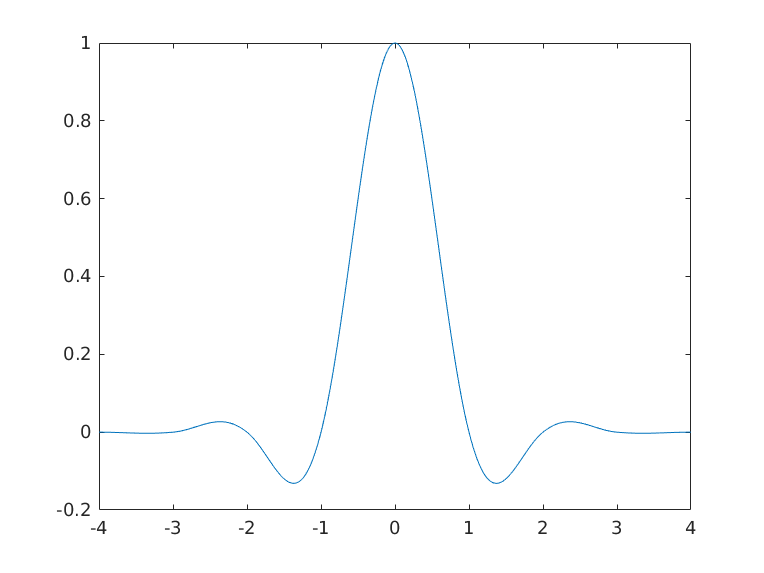

clearvars phi; clear
p = 7; % the width of our stencil "the GD p" 
d = 1; % the continuity of our interpolant.
c = 0; % we want the solution, c = 1 would give the derivative of the solution
xi = -4:.01:4; % the range we wish to plot
for i = 1:length(xi)
    phi(i) = DSICK_phi(xi(i),p,d,c); % evaluate the basis function at each phi
end
plot(xi,phi);

Note, as of this initial version, DSICK_phi has not been "vectorized". Thus we have to loop over each point. 

Now that we can make our basis functions, we can close off our domain by constructing our D - Copatibility Coefficients. These are the equations that tell us how we fill in ghost data. 

p = 7;
ng = (p-1)/2; % number of ghost points
BCond = [0,2]; % specify conditions on the function and its second derivative
if any(BCond == 0)
    nCompat = length(BCond)-1;  %% set 1 less condition
else
    nCompat = length(BCond); 
end %if
extrapOrd = p+1; % Other numbers are possible, p+1 works "best"
weights = DSICK_getDCompatCoeffs(nCompat,ng,p,extrapOrd,BCond)

weights =     1.0000   -8.0000   28.0000  -56.0000   70.0000  -56.0000   28.0000   -8.0000    1.0000         0         0         0
         0    1.0000   -8.0000   28.0000  -56.0000   70.0000  -56.0000   28.0000   -8.0000    1.0000         0         0
         0         0    1.0000   -0.5556   -3.8571    6.7857   -5.3175    2.5714   -0.7143    0.0873         0         0


No we can use our basis functions to interpolat some data. This functionality has been included and can be done by using the ``evalU`` function.

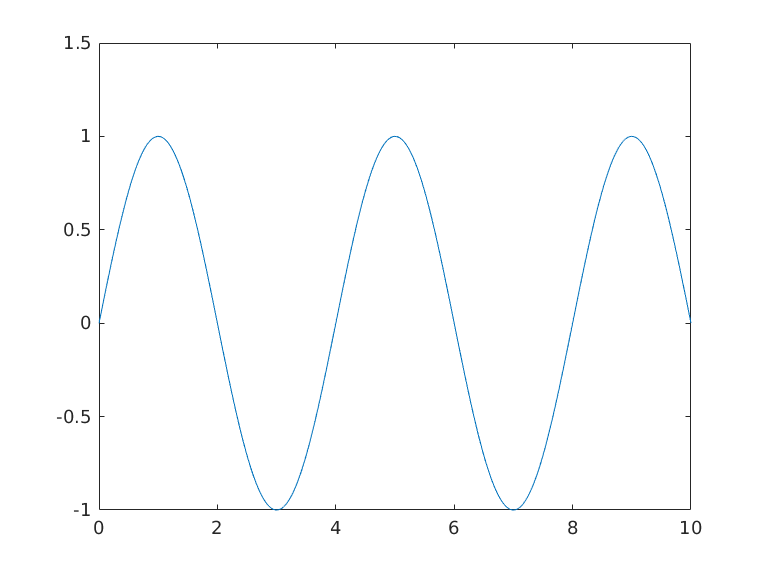

fexact = @(x) sin(.5*pi*x);
xcourse = 0:.1:10; %this will give us our data
courseData = fexact(xcourse);
xfine = 0:.01:10; %we want to interpolate the data at these points
p = 7; d = 1; c = 0; 
BCondLeft = [0,2]; % Some information about the boundaries so we...
BCondRight= [0,2]; % can use D-Compat Closure.
ux = DSICK_evalU(courseData,xcourse,p,d,c,xfine,BCondLeft,BCondRight);
plot(xfine,ux)

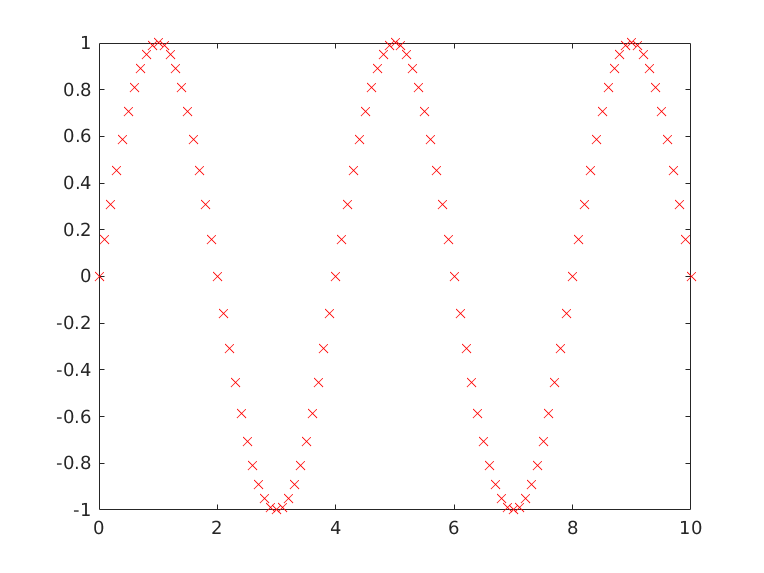

hold on
plot(xcourse,courseData,'rx')

And since we can, lets take a look at the error too.

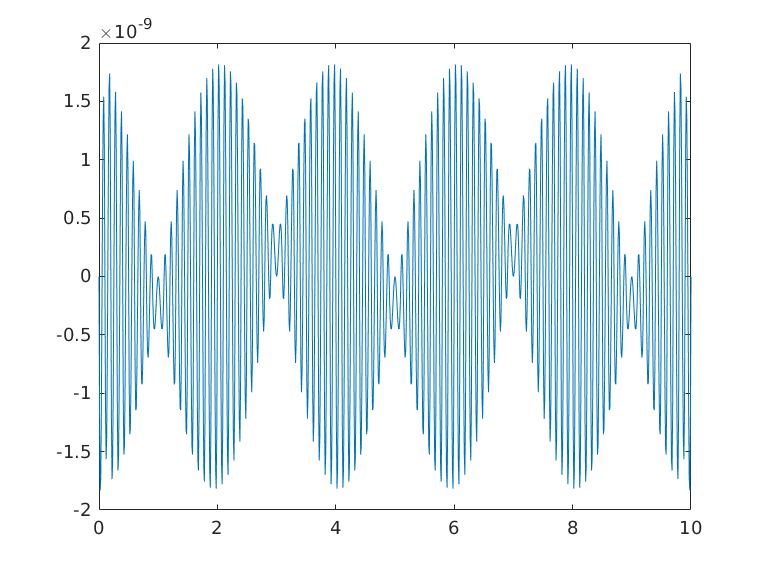

fexactData = fexact(xfine);
plot(xfine,ux-fexactData)